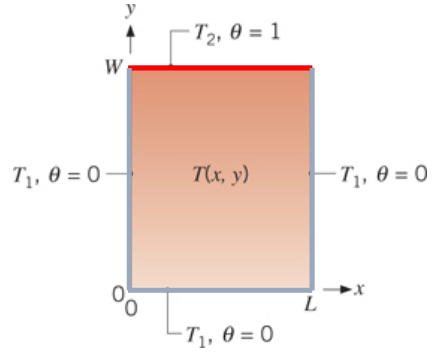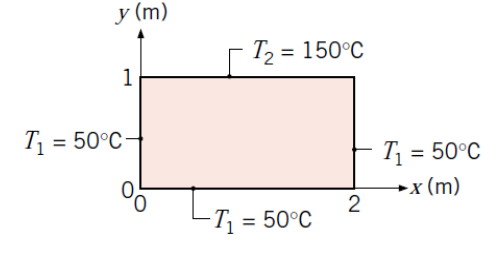

clear all
clf
syms theta(x,y) x y T(x,y) T_diff_x(x,y) T_diff_y(x,y)
T2 = 150 + 273.15;
T1 = 50 + 273.15;
n_end = 40; % antal led på polynomiet
W = 1; %højde
L = 2; %brede
sums = 0;


Equations

for n = 1:n_end
    sum_n = ((-1)^(n+1) + 1) / n * sin(n * pi * x / L) * sinh(n*pi*y/L) / sinh(n*pi*W/L);
    sums = sums + sum_n;
end

theta(x,y) = 2/pi * sums;
T(x,y) = T2 - T1*theta(x,y) + T2*theta(x,y);
% eq = theta1 == (Ttest - T2)/(T2-T1);
% Ttest = solve(eq, Ttest)

T_diff_x(x,y) = diff(T(x,y), x);
T_diff_y(x,y) = diff(T(x,y), y);

Mesh creation

scalar_filed_size = 10;  % change sizes here
x_lin = linspace(0,L,scalar_filed_size);
y_lin = linspace(0,W,scalar_filed_size);

for i = 1:scalar_filed_size
    for j = 1:scalar_filed_size
        scalar_field(i,j) = T(x_lin(i),y_lin(j));
        DX(i,j) = T_diff_x(x_lin(i),y_lin(j));
        DY(i,j) = T_diff_y(x_lin(i),y_lin(j));
    end
end

[X,Y] = meshgrid(x_lin,y_lin);
%rotation of the grid to mach figure
X = X'; 
Y = Y';

Plot

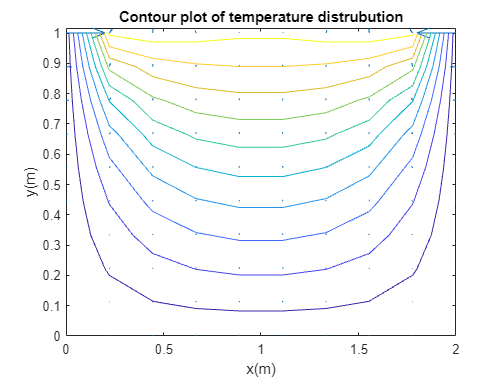

q = quiver(X,Y,DX,DY);
hold on
contour(X,Y,scalar_field)
title('Contour plot of temperature distrubution')
ylabel('y(m)')
xlabel('x(m)')
% q.ShowArrowHead = 'off';
% q.Marker = '.';
% q.AutoScaleFactor(0.5)
hold off


fieldvals = double(vpa(scalar_field))

fieldvals =   423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500
  423.1500  426.8511  430.7717  435.1771  440.4456  447.1908  456.5103  470.4489  492.2843  522.0439
  423.1500  429.7428  436.6206  444.0957  452.5355  462.3842  474.1514  488.2950  504.8910  525.4462
  423.1500  431.5391  440.1725  449.2937  459.1388  469.9193  481.7846  494.7605  508.6806  524.0908
  423.1500  432.3585  441.7670  451.5634  461.9087  472.9181  484.6390  497.0288  509.9430  521.9174
  423.1500  432.3585  441.7670  451.5634  461.9087  472.9181  484.6390  497.0288  509.9430  521.9174
  423.1500  431.5391  440.1725  449.2937  459.1388  469.9193  481.7846  494.7605  508.6806  524.0908
  423.1500  429.7428  436.6206  444.0957  452.5355  462.3842  474.1514  488.2950  504.8910  525.4462
  423.1500  426.8511  430.7717  435.1771  440.4456  447.1908  456.5103  470.4489  492.2843  522.0439
  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.1500  423.150

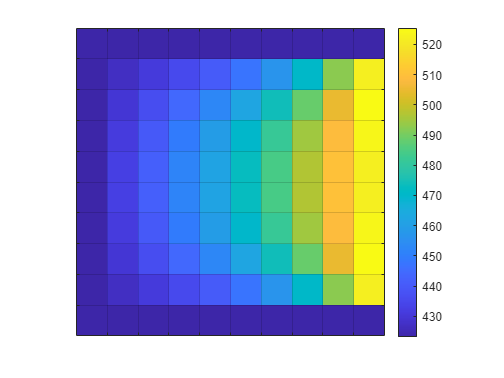


% Plot the matrix as a grid
figure; % Open a new figure window
imagesc(fieldvals); % Display the matrix as an image
colorbar; % Optionally, add a colorbar to indicate the scale of values
axis square; % Make the plot square shaped

% Enhance the grid visibility
ax = gca; % Get current axis
ax.GridColor = 'k'; % Set grid color to black
ax.GridLineStyle = '-'; % Set grid line style
ax.XTick = 0.5:1:50.5; % Set x-ticks to appear between cells
ax.YTick = 0.5:1:50.5; % Set y-ticks to appear between cells
ax.XTickLabel = []; % Remove x-tick labels
ax.YTickLabel = []; % Remove y-tick labels
ax.XGrid = 'on'; % Turn on x-grid
ax.YGrid = 'on'; % Turn on y-grid
box on; % Enclose the plot in a box

% Compute the gradient of Z
[U, V] = gradient(fieldvals);

U = -U

U =          0         0         0         0         0         0         0         0         0         0
   -3.7011   -3.8109   -4.1630   -4.8369   -6.0068   -8.0324  -11.6290  -17.8870  -25.7975  -29.7596
   -6.5928   -6.7353   -7.1765   -7.9575   -9.1442  -10.8080  -12.9554  -15.3698  -18.5756  -20.5551
   -8.3891   -8.5113   -8.8773   -9.4831  -10.3128  -11.3229  -12.4206  -13.4480  -14.6652  -15.4102
   -9.2085   -9.3085   -9.6025  -10.0709  -10.6774  -11.3651  -12.0553  -12.6520  -12.4443  -11.9743
   -9.2085   -9.3085   -9.6025  -10.0709  -10.6774  -11.3651  -12.0553  -12.6520  -12.4443  -11.9743
   -8.3891   -8.5113   -8.8773   -9.4831  -10.3128  -11.3229  -12.4206  -13.4480  -14.6652  -15.4102
   -6.5928   -6.7353   -7.1765   -7.9575   -9.1442  -10.8080  -12.9554  -15.3698  -18.5756  -20.5551
   -3.7011   -3.8109   -4.1630   -4.8369   -6.0068   -8.0324  -11.6290  -17.8870  -25.7975  -29.7596
         0         0         0         0         0         0         0         0       

V = -V

V =          0   -3.7011   -7.6217  -12.0271  -17.2956  -24.0408  -33.3603  -47.2989  -69.1343  -98.8939
         0   -3.2964   -6.7353  -10.4728  -14.6928  -19.6171  -25.5007  -32.5725  -40.8705  -51.1481
         0   -2.3440   -4.7004   -7.0583   -9.3466  -11.3643  -12.6372  -12.1558   -8.1982   -1.0234
         0   -1.3078   -2.5732   -3.7338   -4.6866   -5.2670   -5.2438   -4.3669   -2.5260    1.7644
         0   -0.4097   -0.7972   -1.1349   -1.3850   -1.4994   -1.4272   -1.1341   -0.6312    1.0867
         0    0.4097    0.7972    1.1349    1.3850    1.4994    1.4272    1.1341    0.6312   -1.0867
         0    1.3078    2.5732    3.7338    4.6866    5.2670    5.2438    4.3669    2.5260   -1.7644
         0    2.3440    4.7004    7.0583    9.3466   11.3643   12.6372   12.1558    8.1982    1.0234
         0    3.2964    6.7353   10.4728   14.6928   19.6171   25.5007   32.5725   40.8705   51.1481
         0    3.7011    7.6217   12.0271   17.2956   24.0408   33.3603   47.2989   69.1

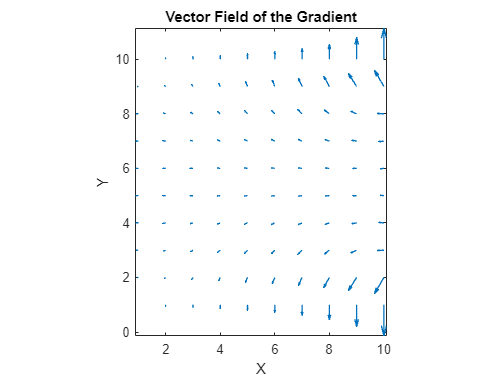


% Create a grid of coordinates for plotting
[x, y] = meshgrid(1:10, 1:10); % Adjust the range if necessary

% Plot the vector field using quiver
figure; % Open a new figure window
quiver(x, y, U, V, 'LineWidth', 1, 'MaxHeadSize', 3);
title('Vector Field of the Gradient');
xlabel('X');
ylabel('Y');
axis tight equal; % Adjust the axis scaling and limits

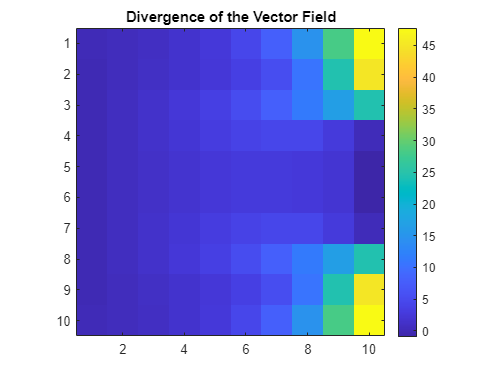

% Calculate the divergence
[x, y] = meshgrid(1:10, 1:10); % Create a grid of coordinates for your field
divergenceValue = divergence(x, y, U, V);

% Plot the divergence as a color map
figure;
imagesc(divergenceValue);
colorbar; % Add a color bar to indicate the scale of divergence values
title('Divergence of the Vector Field');
axis tight; % Fit the axis tightly around the data
axis equal; % Keep the aspect ratio of the plot square